# The MathWorks Power Company

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

You are now an employee of the MathWorks power company, your mission is to design an hydropower plant to provide enough electricity to power all of MathWorks data center in its headquarter in Natick. The project would be to buil an aritificial mountain in the shape of MATLAB's membrane logo with a lake at its center. The lake collects water all year and this water is used to generate

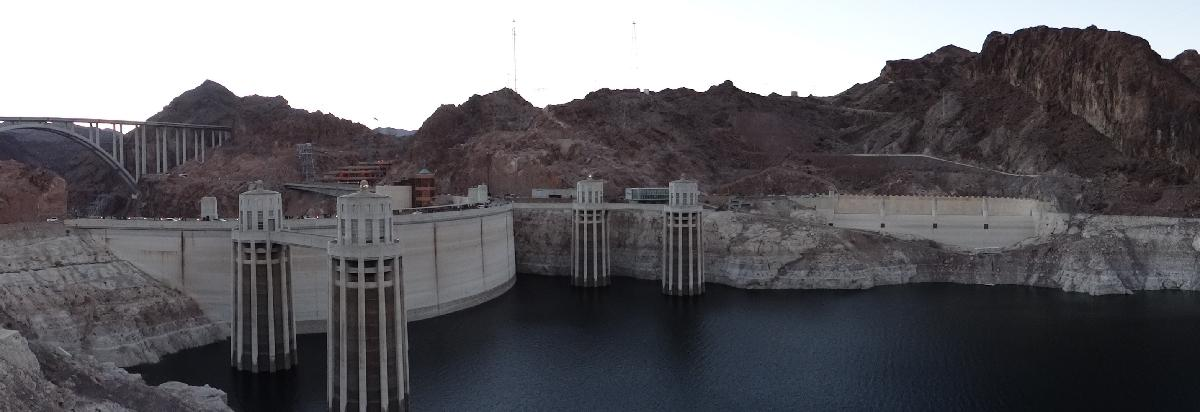

Hoover Dam intake tower from lake Mead, [USGS](https://www.usgs.gov/media/images/hoover-dam-intake-towers-panorama)

## Introduction

### What is energy?

In a fluid, energy refers to the ability of a fluid to produce work. It takes various form:

- Kinetic energy refers to the energy of motion

- Potential energy refers to the energy associated with a conservative external fields such as gravity

- Internal energy refers to the molecular internal energy of the fluid

  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Energy")


All units of dimension 'Energy':

erg - erg
eV - electronvolt
E_h - Hartree energy 
J - joule ['SI']
kpm - kilopond meter
Wh - watt hour
Ws - watt second

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



### What is power?

Power refers to the rate at which energy is transferred. It is typically measured in units of energy per unit of time, such as Watts (W) or horsepower (hp).

  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Power")


All units of dimension 'Power':

HP_DIN - metric horsepower (DIN 66036)
HP_E - electrical horsepower
HP_I - mechanical horsepower
HP_UK - British imperial horsepower
poncelet - poncelet
PS_DIN - horsepower (DIN 70020)
PS_SAE - net horsepower (SAE J1349)
W - watt ['SI']

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



**Reflect. **Multiple dimension of horsepower.

### Need analysis

## Application: Wind Turbine

In this section, we are going to analyze the performance of a wind turbine by:

- Applying the [Control Volume](matlab:open('./ManOnTheMoon.mlx')) method

- Solving a simple power balance of the system

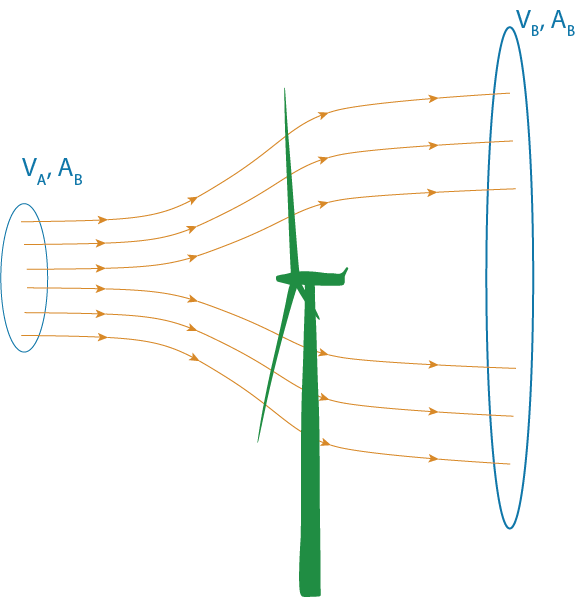

### **Control Volume**

We consider the control volume as describe as in the previous figure. All the mass flow coming in the control volume volume through the surface A, must exit the control volume through surface B. Therefore we can write the following mass flow equilibrium:


$$\rho S_A v_A = \rho S_B v_B = \rho S_t v_t = \dot{m}$$


where $\rho$ is the density, $(S_A,S_B,S_t)$ are the arar of surface A, B and the area of the turbine, and $(v_A,v_B,v_t)$ are the velocity of the flow through the surface A, B and the turbine itself.

  **Try. **Define the parameter of the problem.

syms rho S_A S_B S_t v_A v_B v_t
m_dot = rho*S_t*v_t

$$avgAnnualPower = 100\,\mathrm{kW}$$

The momentum conservation equation is th


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV}_\text{Acceleration}
+
\underbrace{\int_{CS}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS}_\text{Thrust}
=
\sum\vec{F}$$


We are considering the flow to be at steady-state, so the derivative with respect to time is equal to 0. There is no radial flow, so all the air entering the turbine upstream is exiting the turbine downstream. Therefore, we are left with:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
+
\int_\text{downstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
=
\vec{F}_\text{turbine\rightarrow air}$$


The upstream term can be expressed as:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
=
-\dot{m}\vec{v_A}$$


 **Exercise. **Complete the expression of $F_\text{turbine\rightarrow air}$ in `F_ta`, using it to compute F_at $XXX$. You can use the simplify function to make the results more readable.

F_ta = - m_dot*v_A + m_dot*v_B;

$$annualEnergy = 100\,\mathrm{kW}\,{\mathrm{year}}_{\mathrm{Julian}}$$

F_at = simplify(- F_ta)


$$dE = F dx$$



$$P = \frac{dE}{dt} = F\frac{dx}{dt} = Fv$$


P_at = simplify(F_at * v_t)

$$annualEnergy = 876600\,h\,\mathrm{kW}$$

### **Power Balance**


$$P_\text{air\rightarrow turbine} = P_A - P_b \quad\quad (\clubsuit)$$


 **Exercise. **Write the power of the fluid going through surface A and surface B in `P_A` and `P_B.`

P_A = 1/2*m_dot*v_A^2;

$$annualCost = 262980$$

P_B = 1/2*m_dot*v_B^2;

 **Exercise. **Write $(\clubsuit)$ in `PowerBalance.`

PowerBalance = P_at == P_A - P_B

$$riverFlow = 2.8667\,\frac{m^{3}}{s}$$

 **Exercise. **Solve the power balance to express $v_t$ as a function of $v_A$ and $v_B$, save the results in v_Sol

v_Sol = solve(PowerBalance, v_t)

$$riverAnnualDischarge = 90465120\,m^{3}$$

**Reflect. **

v_Sol = v_Sol(2)

$$deltaPDam = 3.5571\,\mathrm{mH2O}$$

 **Exercise. **Solve

P_at = subs(P_at,v_t, v_Sol)

XXX Check answer and iterate on it

 **Exercise. **Solve

P_0 = 1/2*rho*S_t*v_A^3

 **Exercise. **Solve

% Declare the efficient eta = P_at/P_0
eta = P_at/P_0
% Substitute v_B by x*v_A, this should rewrite the equation as a function
% of x = v_B/v_a
syms x
eta = simplify(subs(eta, v_B, x*v_A))

% Plotting function
fplot(x,100*eta,[0 1])
xlabel("$x=\frac{v_2}{v_1}$",Interpreter="latex")
ylabel("\eta (%)")
title("Efficiency of wind turbine")

## Feasibility study

[Picture of the Apple Hill data center]

 **Exercise. **using MATLAB smbolic unit system, define a variable name `avgPower` that represents the average annual power use of the data center

u = symunit;
avgAnnualPower = 100*u.kW

 **Exercise. **Compute the total energy that such data center would be using

annualEnergy = avgAnnualPower * u.year

 **Exercise. **Convert this energy use in kWh

annualEnergy = unitConvert(annualEnergy,u.kW*u.hour)

 **Exercise. **Estimate the cost of at 0.3$/kWh

annualCost = simplify(annualEnergy * 0.3 / u.kWh)

### Option 1: Building a dam on the Charles river

riverFlow = 1/3*8.6*u.m^3/u.s
riverAnnualDischarge = riverFlow * 1*unitConvert(u.year,u.s)
deltaPDam = unitConvert(annualEnergy /riverAnnualDischarge, u.mH2O)

Environmental impact?

### Option 2: Build a large rainwater retention lake

DeltaP = 9.81*1000*10*u.Pa 
VolumeWater = TotalEnergy/DeltaP;
VolumeWater = unitConvert(VolumeWater,u.m^3)
AnnualPrecipitation = 1.11*u.m;
SurfaceCaptation = VolumeWater/AnnualPrecipitation
SurfaceCaptation = unitConvert(SurfaceCaptation,u.km^2)

MathWorks is actually going to Solar and Wind instead: [MathWorks Carbon Neutral Innitiative](https://www.mathworks.com/company/aboutus/carbon-neutral.html)

## Modeling power generated from a retention lake

### Introduction

S = 600 * u.km^2
h = 10 * u.m
plotRetentionLake()

### Mathematical model


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{res}\frac{dh_\text{res}}{dt} = \dot{m}_\text{rain}-\dot{m}_\text{evap}-\dot{m}_\text{turbine}$$


#### Model the rainfall

load NatickWeather.mat
weather
figure
plot(weather,"time","Temp")
hold on
plot(weather,"time","DewPoint")
hold off
title("Temperature and Dew Point in Natick, MA")
ylabel("(^\circ{C})")
xlabel("date")
legend("Air Temperature", "Dew Point","Location","best")
firstDate = datetime(2022,4,11);
Duration = 5;
xlim([firstDate,firstDate+Duration*days]);

% Retime timetable
dailyWeather = retime(weather(:,[1 2 3 5]),"regular","mean",...
    "TimeStep",caldays(1));

% Retime each override variable to same time vector
TT = retime(weather(:,"Rainfall"),dailyWeather.Properties.RowTimes,"sum");
dailyWeather = addvars(dailyWeather,TT.(1),'Before',4,...
    'NewVariableNames',"Rainfall");
clear TT

% Display results
dailyWeather
dailyWeather.E0 = (700*dailyWeather.Temp/(100-42.3)+15*(dailyWeather.Temp-dailyWeather.DewPoint))./(80-dailyWeather.Temp)
plot(dailyWeather.E0)

#### Model the evaporation

#### Model the flow through the turbine

## Helper Functions

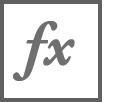`plotRetentionLake()`

function plotRetentionLake()
    Z = membrane(1,10);
    Z = [[fliplr(Z) Z]; flipud([fliplr(Z) Z])];
    n = size(Z,1);
    [X,Y] = meshgrid(0:n-1,0:n-1);
    X = 2*X/(n-1) - 1;
    Y = 2*Y/(n-1) - 1;
    C = zeros(size(Z));
    C(11:31,11:31) = 1.0;
    Z(1,:) = 0.0;
    Z(end,:) = 0.0;
    Z(:,1) = 0.0;
    Z(1,end) = 0.0;
    Z( Z < 0 ) = 0.0;
    X = X * 100;
    Y = Y * 100;
    s = surf(X,Y,Z,C,"FaceColor","flat","EdgeColor","k");
    view([-64 59])
    mapFace = [0.3 0.3 0.3
               0.83 0.94 0.97];
    colormap(mapFace)
end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc